wellID = 1;
numSeconds = 0.8;
resolution = 10;
samplingFrequency = 20000;
startSample = 1;
highPassCutOff = 1;
bandwidth = [950 1000];
correctionFactor = 2;

cells2Media = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003425/ActivityScan/000004/data.raw.h5'

cells2Media = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003425/ActivityScan/000004/data.raw.h5'

rawData_cells2Media = mxw.fileManager(cells2Media,wellID);

cells2H14_5 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003375/ActivityScan/000021/data.raw.h5'

cells2H14_5 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003375/ActivityScan/000021/data.raw.h5'

rawData_cells2H14_5 = mxw.fileManager(cells2H14_5,wellID);

cells2H21 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003387/ActivityScan/000028/data.raw.h5'

cells2H21 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003387/ActivityScan/000028/data.raw.h5'

rawData_cells2H21 = mxw.fileManager(cells2H21,wellID);

cells2H48 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260117/P003425/ActivityScan/000034/data.raw.h5'

cells2H48 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260117/P003425/ActivityScan/000034/data.raw.h5'

rawData_cells2H48 = mxw.fileManager(cells2H48,wellID);

cells2H72 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260118/P003425/ActivityScan/000035/data.raw.h5'

cells2H72 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260118/P003425/ActivityScan/000035/data.raw.h5'

rawData_cells2H72 = mxw.fileManager(cells2H72,wellID);

cells2H96 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260119/P003375/ActivityScan/000041/data.raw.h5'

cells2H96 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260119/P003375/ActivityScan/000041/data.raw.h5'

rawData_cells2H96 = mxw.fileManager(cells2H96,wellID);


cells2H120 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260120/P003425/ActivityScan/000046/data.raw.h5'

cells2H120 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260120/P003425/ActivityScan/000046/data.raw.h5'

rawData_cells2H120 = mxw.fileManager(cells2H120,wellID);

cells2H144 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260121/P003425/ActivityScan/000051/data.raw.h5'

cells2H144 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260121/P003425/ActivityScan/000051/data.raw.h5'

rawData_cells2H144 = mxw.fileManager(cells2H144,wellID);

cells2H168 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260122/P003425/ActivityScan/000057/data.raw.h5'

cells2H168 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260122/P003425/ActivityScan/000057/data.raw.h5'

rawData_cells2H168 = mxw.fileManager(cells2H168,wellID);

cells2H192 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260123/P003425/ActivityScan/000063/data.raw.h5'

cells2H192 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260123/P003425/ActivityScan/000063/data.raw.h5'

rawData_cells2H192 = mxw.fileManager(cells2H192,wellID);

cells2D14 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260129/P003425/ActivityScan/000070/data.raw.h5'

cells2D14 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260129/P003425/ActivityScan/000070/data.raw.h5'

rawData_cells2D14 = mxw.fileManager(cells2D14,wellID);


cells2D14_2 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260129/P002645/ActivityScan/000075/data.raw.h5'

cells2D14_2 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260129/P002645/ActivityScan/000075/data.raw.h5'

rawData_cells2D14_2 = mxw.fileManager(cells2D14_2,wellID);



table_cells2Media = createActivityScanTable(rawData_cells2Media,startSample,numSeconds,correctionFactor);
table_cells2Media = highPassFilterTraces(table_cells2Media,highPassCutOff,samplingFrequency);
[table_cells2Media, AvPSD_cells2Media, Avfreq_cells2Media] = calculatePSDs(table_cells2Media,samplingFrequency,resolution);

[RMS_cells2Media] = calculateAverageRMS(AvPSD_cells2Media,Avfreq_cells2Media,bandwidth,resolution);
disp(RMS_cells2Media);

   2.5461e-07




table_cells2Media = calculateRMSs(table_cells2Media, bandwidth,resolution);
table_cells2Media = calculateResistances(table_cells2Media, bandwidth);

%table_cellsMedia = addSurfaceScanData(table_cellsMedia,surfaceScan_cellsMedia);

[table_cells2H14_5,av1,diff1,~,~] = runAnalysis(rawData_cells2H14_5,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,2);

   4.3144e-08




[table_cells2H21,av2,diff2,~,~] = runAnalysis(rawData_cells2H21,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,2);

   4.4751e-08




[table_cells2H48,av3,diff3,~,~] = runAnalysis(rawData_cells2H48,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,2);

   6.5192e-08



[table_cells2H72,av4,diff4,~,~] = runAnalysis(rawData_cells2H72,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,2);

   1.1262e-07



[table_cells2H96,av5,diff5,~,~] = runAnalysis(rawData_cells2H96,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,2);

   2.0643e-07



[table_cells2H120,av6,diff6,~,~] = runAnalysis(rawData_cells2H120,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,2);

   2.8927e-07



[table_cells2H144,av7,diff7,~,~] = runAnalysis(rawData_cells2H144,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,2);

   3.4264e-07



[table_cells2H168,av8,diff8,~,~] = runAnalysis(rawData_cells2H168,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,2);

   3.7104e-07



[table_cells2H192,av9,diff9,~,~] = runAnalysis(rawData_cells2H192,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,2);

   3.7260e-07



[table_cells2D14,av10,diff10,~,~] = runAnalysis(rawData_cells2D14,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,1);

   3.4325e-07



[table_cells2D14_2,av11,diff11,~,~] = runAnalysis(rawData_cells2D14_2,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_cells2Media,1);

   3.3996e-07



clf;

loglog(Avfreq_cells2Media,sqrt(diff2))


hold on
loglog(Avfreq_cells2Media,sqrt(diff3))

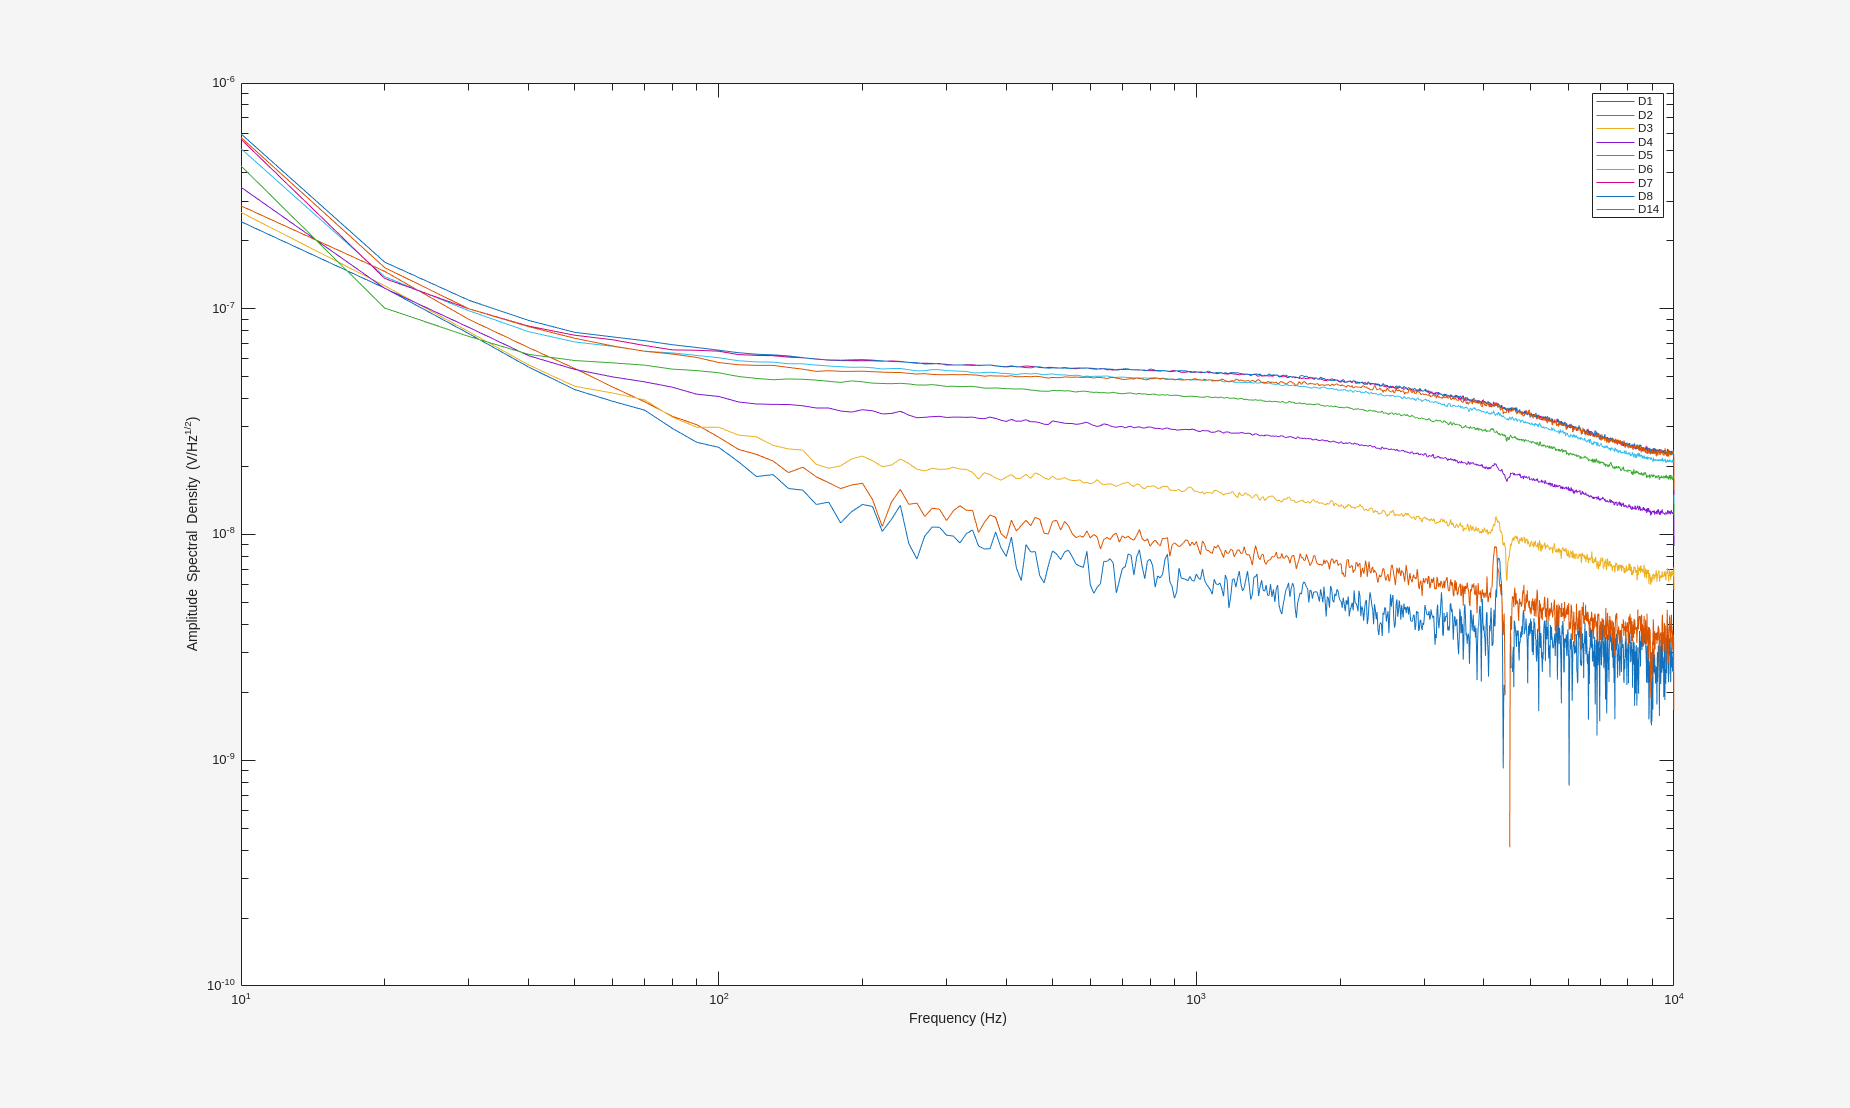

hold off
hold on
loglog(Avfreq_cells2Media,sqrt(diff4))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(diff5))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(diff6))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(diff7))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(diff8))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(diff9))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(diff10))
hold off

ax = gca;

xlabel(ax,'Frequency (Hz)');
ylabel(ax,'Amplitude Spectral Density (V/Hz^{1/2})');

legend('D1','D2','D3','D4','D5','D6','D7','D8','D14')

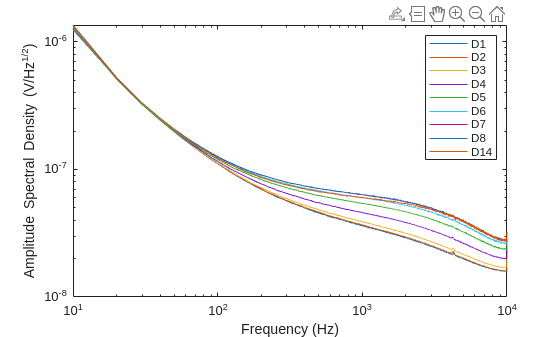

clf;

loglog(Avfreq_cells2Media,sqrt(av2))

hold on
loglog(Avfreq_cells2Media,sqrt(av3))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(av4))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(av5))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(av6))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(av7))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(av8))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(av9))
hold off
hold on
loglog(Avfreq_cells2Media,sqrt(av10))
hold off
ax = gca;

xlabel(ax,'Frequency (Hz)');
ylabel(ax,'Amplitude Spectral Density (V/Hz^{1/2})');

legend('D1','D2','D3','D4','D5','D6','D7','D8','D14')

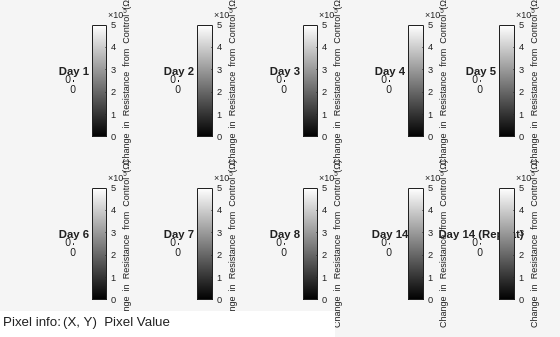

clf;
figure;
t = tiledlayout(2,5);
scale = [0 500e3]

nexttile;

plotSingleResistanceHeatmap(table_cells2H21,'Day 1', scale);

nexttile;

plotSingleResistanceHeatmap(table_cells2H48,'Day 2', scale);

nexttile;

plotSingleResistanceHeatmap(table_cells2H72,'Day 3', scale);

nexttile;

plotSingleResistanceHeatmap(table_cells2H96,'Day 4', scale);

nexttile;

plotSingleResistanceHeatmap(table_cells2H120,'Day 5', scale);

nexttile;

plotSingleResistanceHeatmap(table_cells2H144,'Day 6', scale);

nexttile;

plotSingleResistanceHeatmap(table_cells2H168,'Day 7', scale);

nexttile;

plotSingleResistanceHeatmap(table_cells2H192,'Day 8', scale);

nexttile;

plotSingleResistanceHeatmap(table_cells2D14,'Day 14', scale);




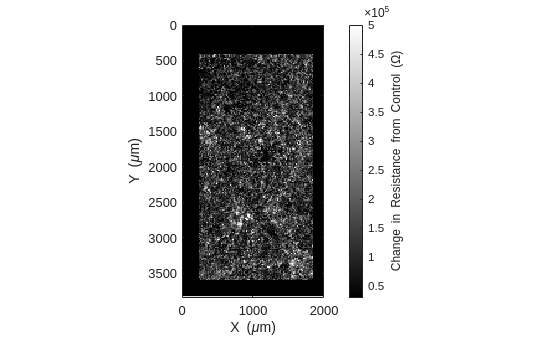


figure;

Z = reshape(transpose(table_cells2D14.diffResistances),220,120);
ax = gca;
imagesc(ax,table_cells2D14.xs,table_cells2D14.ys,Z);

axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[30e3 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

cellsD14 = 'C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\26_01_10_Neurons\260129\260129\P003425\ActivityScan\000070\data.raw.h5';
rawData_cellsD14 = mxw.fileManager(cellsD14,1);
tableCellsD14 = createActivityScanTable(rawData_cellsD14,1,1,1);


ampDataPath = 'C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\26_01_10_Neurons\260129\260129\P003425\ActivityScan\000070\analysis\ActivityAnalysis_v1\0001\Well1\.swlib\amplitudeMap.svg.csv';
tableCellsD14 = addAmplitudeMapData(tableCellsD14,ampDataPath)

tableCellsD14 = 26400×6 table
    electrodeNums    hasTraces     xs       ys        rawTraces       maxAmplitudes
    _____________    _________    ____    ______    ______________    _____________

          0            false      17.5      3815    1×20000 double          0      
          1            false      17.5    3797.5    1×20000 double          0      
          2            false      17.5      3780    1×20000 double          0      
          3            false      17.5    3762.5    1×20000 double          0      
          4            false      17.5      3745    1×20000 double          0      
          5            false      17.5    3727.5    1×20000 double          0      
          6            false      17.5      3710    1×20000 double          0      
         

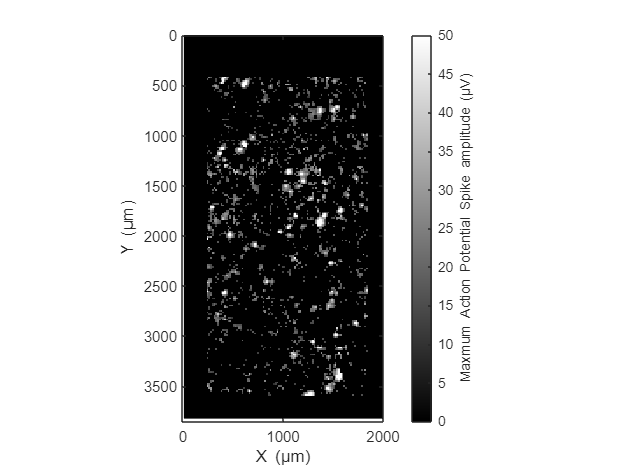

plotSingleAmplitudeHeatmap(tableCellsD14,'Day 14', [0 50]);

rateDataPath = "C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\26_01_10_Neurons\260129\260129\P003425\ActivityScan\000070\analysis\ActivityAnalysis_v1\0001\Well1\.swlib\firingRateMap.svg.csv";

tableCellsD14 = addFiringRateMapData(tableCellsD14,rateDataPath)

tableCellsD14 = 26400×8 table
    electrodeNums    hasTraces     xs       ys        rawTraces       maxAmplitudes    maxFiringRate    maxFiringRates
    _____________    _________    ____    ______    ______________    _____________    _____________    ______________

          0            false      17.5      3815    1×20000 double          0                0                0       
          1            false      17.5    3797.5    1×20000 double          0                0                0       
          2            false      17.5      3780    1×20000 double          0                0                0       
          3            false      17.5    3762.5    1×20000 double          0                0        

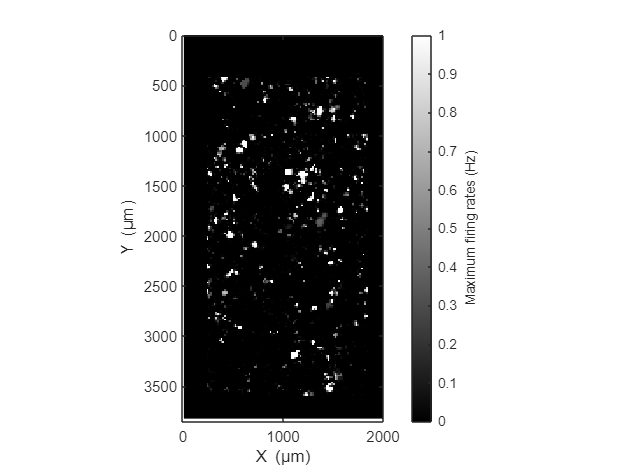

plotSingleFiringRateHeatmap(tableCellsD14,'Day 14', [0 1]);

cellsD14Axon = "C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\26_01_10_Neurons\260129\260129\P003425\AxonTracking\000071\data.raw.h5";
rawData_cellsD14Axon = mxw.fileManager(cellsD14Axon,1);
tableCellsD14axon = createActivityScanTable(rawData_cellsD14Axon,1,1,1);

function T = createSerialRecordingTable(rawData,startSample,numSeconds,correctionFactor,recordingNum)
        

        numSamples = numSeconds*rawData.fileObj(1).samplingFreq;
        [electrodeNums, xs,ys] = calculateXYCoords(rawData);
        
        rawTraces = zeros(length(electrodeNums),numSamples);
        hasTraces = false(length(electrodeNums),1);

        T = table(electrodeNums,hasTraces,xs,ys,rawTraces);
        
        [rawTracesInScan,~,electrodesInScan] = rawData.extractRawData(startSample,numSamples,'file',recordingNum);
        electrodesInScan = transpose(cell2mat(electrodesInScan));

        rawTracesInScan = transpose((rawTracesInScan./(1E6))*correctionFactor);
        [inTable, location] = ismember(T.electrodeNums, electrodesInScan);
        T.rawTraces(inTable,:) = rawTracesInScan(location(inTable),:);
        T.hasTraces(inTable) = true;
     
end

function T = createActivityScanTable(rawData,startSample,numSeconds,correctionFactor)
        

        numSamples = numSeconds*rawData.fileObj(1).samplingFreq;
        [electrodeNums, xs,ys] = calculateXYCoords(rawData);
        
        rawTraces = zeros(length(electrodeNums),numSamples);
        hasTraces = false(length(electrodeNums),1);

        T = table(electrodeNums,hasTraces,xs,ys,rawTraces);
        
        n = rawData.nRecordings;

        for recordingNum = 1:n
            [rawTracesInScan,~,electrodesInScan] = rawData.extractRawData(startSample,numSamples,'file',recordingNum);
            electrodesInScan = transpose(cell2mat(electrodesInScan));

            rawTracesInScan = transpose((rawTracesInScan./(1E6))*correctionFactor);
            [inTable, location] = ismember(T.electrodeNums, electrodesInScan);
            T.rawTraces(inTable,:) = rawTracesInScan(location(inTable),:);
            T.hasTraces(inTable) = true;

        end
     
end




function T = createFullElectrodeTable(rawData)

           [electrodeNums, xs, ys] = calculateXYCoords(rawData);
           
           T = table(electrodeNums,xs,ys);
 
end

function T = addSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    T = addvars(T,scanT.Var2,'NewVariableNames','surfaceScanVals');

end


function T = addAmplitudeMapData(T,filename)

    zs = zeros(height(T),1);

    T = addvars(T,zs,'NewVariableNames','maxAmplitudes');

    ampT = readtable(filename);

    ampT = sortrows(ampT);
    inTable = ismember(T.electrodeNums,ampT.electrodes);

   
    i=1;
    for j = 1:height(T)
        if inTable(j)
            T.maxAmplitudes(j) = ampT.elecAmplitude(i);
            i=i+1;
        end
    end
    
    
    
end


function T = addFiringRateMapData(T,filename)

    zs = zeros(height(T),1);

    T = addvars(T,zs,'NewVariableNames','maxFiringRates');

    rateT = readtable(filename);

    rateT = sortrows(rateT);
    inTable = ismember(T.electrodeNums,rateT.electrodes);

   
    i=1;
    for j = 1:height(T)
        if inTable(j)
            T.maxFiringRates(j) = rateT.elecFiringRate(i);
            i=i+1;
        end
    end
    

    
end

function T = calculateDifferentialSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    diffVals = T.surfaceScanVals - scanT.Var2;

    T = addvars(T,diffVals,'NewVariableNames','diffSurfaceScanVals');

end

    
function T = highPassFilterTraces(T, highPassCutOff,samplingFreq)
        
        [sos,g] = butter(1,highPassCutOff/(samplingFreq/2),"high");
        filteredTraces = filtfilt(sos,g,double(transpose(T.rawTraces)));
        T = addvars(T,transpose(filteredTraces),'NewVariableNames','filteredTraces');
        
end

function [T, avPSD, avFreq] = calculatePSDs(T,samplingFreq,resolution)
    
        

        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        [PSDs,frequencies] = pwelch(transpose(T.filteredTraces),window,overlap,nfft,samplingFreq);
        
        
        avPSD = sum(PSDs,2)/(sum(T.hasTraces)); 

        avFreq = frequencies;

        frequencies = repmat(frequencies,1,size(PSDs,2));
        PSDs = transpose(PSDs);
        frequencies = transpose(frequencies);

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  
        
end

function [T, avPSD, avFreq] = calculateSubsetPSDs(T,samplingFreq,resolution,numElectrodes)

        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        PSDs = zeros(height(T),((nfft/2)+1));
        frequencies = zeros(height(T),((nfft/2)+1));

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  

        electrodesCount = 0;
    
        for i=1:height(T)
            if (T.hasTraces(i)) && (electrodesCount <= numElectrodes)

                [T.PSDs(i,:),T.frequencies(i,:)] = pwelch(T.filteredTraces(i,:),window,overlap,nfft,samplingFreq);
                electrodesCount = electrodesCount + 1;
                frequencies = T.frequencies(i,:);
            end
        end

        avPSD = sum(T.PSDs,1)/numElectrodes; 

        avFreq = frequencies;

end




function [T,avDiffPSD] = calculateDifferentialPSDs (T,controlT)

        differentialPSDs = transpose(T.PSDs) - transpose(controlT.PSDs);

        avDiffPSD = sum(differentialPSDs,2)/sum(T.hasTraces);

        T = addvars(T, transpose(differentialPSDs), 'NewVariableNames','diffPSDs');
    
end

function avRMS = calculateAverageRMS(avPSD,avFreq,bandwidth, resolution)

        

        bandwidth = bandwidth./resolution;
        f = avFreq(bandwidth(1):bandwidth(2));
        PSD = avPSD(bandwidth(1):bandwidth(2));

        avRMS = sqrt(trapz(f,PSD));

end




function T = calculateRMSs(T,bandwidth,resolution)

        bandwidth = bandwidth./resolution;
        len = height(T);
        RMSs = zeros(len, 1);
        variances = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            PSD = transpose(T.PSDs(i,bandwidth(1):bandwidth(2)));
            RMSs(i) = sqrt(trapz(f,PSD)); 
            variances(i) = trapz(f,PSD); 
        end

        T = addvars(T, RMSs,variances,'NewVariableNames',{'RMSs','variances'});

end

function T = calculateDifferentialRMSs(T,bandwidth,resolution)

        bandwidth = bandwidth./resolution;
        len = height(T);
        diffVariances = zeros(len, 1);
        diffRMSs = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            diffPSD = transpose(T.diffPSDs(i,bandwidth(1):bandwidth(2)));
            diffRMSs(i) = sqrt(trapz(f,diffPSD)); 
            diffVariances(i) = trapz(f,diffPSD); 
        end

        T = addvars(T, diffRMSs,diffVariances, 'NewVariableNames',{'diffRMSs','diffVariances'});

end

function T = calculateResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        resistances = (transpose(T.variances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(resistances), 'NewVariableNames','resistances');

end


function T = calculateDifferentialResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        diffResistances = (transpose(T.diffVariances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(diffResistances), 'NewVariableNames','diffResistances');

end

function [electrodeNums, xs, ys] = calculateXYCoords(rawData)

        recordingElectrodes = rawData.processedMap.electrode();
        unroutedElectrodes = rawData.processedMap.nonRoutedElec();

        electrodeNums = cat(1,recordingElectrodes,unroutedElectrodes);
        electrodeNums = sort(electrodeNums);
        
        len = length(electrodeNums);
        
        xs = zeros(1,len);
        ys = zeros(1,len);
        
        for i = 1:len
            ys(i) = ceil(i/220) ;
            xs(i) = i - (220*(ys(i)-1));
            
        end

        W = 220; 

        x_rot = ys;
        y_rot = (W - 1) - xs;

        xs = x_rot;
        ys = y_rot;

       
        
        xs = transpose(xs*17.5);
        ys = transpose(ys*17.5);
end

function plotPowerSpectrum(cellsAvFreqArray,cellsAvPSDArray,tAvfreq,tAvPSD,nRecordings,endRecording,titlePlot,ylabelPlot)
        clf('reset');
        
        loglog(cellsAvFreqArray,sqrt(cellsAvPSDArray));
        hold on;
        loglog(tAvfreq,sqrt(tAvPSD));
        hold off;
        
        colorMapLength = nRecordings;
        red = [1,0,0];
        blue = [0,0,1];
        black = [0,0,0];
        
        
        colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
        colours_ctrl = black;
        ax=gca;
        ax.ColorOrder = cat(1,colours_scale,colours_ctrl);
        
        hours = linspace(0,endRecording,nRecordings)+3;
        legendText = cell(1,nRecordings+1);
        
        for i = 1:nRecordings
            legendText{i} = sprintf('Hour %g ',hours(i));
        end
        
        mediaLabel = 'Media Control';
        legendText{nRecordings+1} = mediaLabel;
        legend(string(transpose(legendText)))
        
        xlim([0 5000]);
        xlabel('Frequency (Hz)');
        ylabel(ylabelPlot);
        title(titlePlot);
        set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')
end

function plotPowerSpectrumDiff(cellsAvFreqArray,cellsAvPSDArray,nRecordings,endRecording,titlePlot,ylabelPlot)
        clf('reset');
        
        loglog(cellsAvFreqArray,cellsAvPSDArray);
        
        
        colorMapLength = nRecordings;
        red = [1,0,0];
        blue = [0,0,1];
        black = [0,0,0];
        
        
        colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
        colours_ctrl = black;
        ax=gca;
        ax.ColorOrder = cat(1,colours_scale,colours_ctrl);
        
        hours = linspace(0,endRecording,nRecordings)+3;
        legendText = cell(1,nRecordings);
        
        for i = 1:nRecordings
            legendText{i} = sprintf('Hour %g ',hours(i));
        end
        
     
        legend(string(transpose(legendText)))
        
        xlim([100 3500]);
        xlabel('Frequency (Hz)');
        ylabel(ylabelPlot);
        title(titlePlot);
        set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')
end

function generateMEAVideo(nRecordings,cellsTableArray,filename)
        videoFile = filename;
        
        v = VideoWriter(videoFile, 'Uncompressed AVI');
        v.FrameRate = 2;         
        open(v);
        
        figure;
        set(gcf,'Position',[100 100 700 900], 'Color','w');              
        ax = axes('Position',[0.1 0.1 0.75 0.8]);
        
        
        hours = 1.5;          
        
        for i = 1:nRecordings
        
            cla(ax);
        
            Z = reshape(transpose(cellsTableArray{i}.diffResistances),220,120);
        
            imagesc(ax,cellsTableArray{i}.xs,cellsTableArray{i}.ys,Z);
        
            axis(ax,'equal');
            axis(ax,[0 2000 0 3850]);
            colormap(ax,gray);
            clim(ax,[0 200e3]);
        
            xlabel(ax,'X (\mum)');
            ylabel(ax,'Y (\mum)');
                 
            cb = colorbar(ax);
            cb.Label.String = 'Change in Resistance from Control (\Omega)';
            cb.Location = 'eastoutside';
            
            t_hours = (i-1) * hours + 3;
            title(ax, sprintf('T = %.1f h', t_hours),'FontWeight','bold')
        
            drawnow        
            frame = getframe(gcf);
            writeVideo(v, frame);
        end
        
        close(v);
end


function [tableData, avPSD,avDiffPSD,avFreq,avRMS] = runAnalysis(rawData,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,controlTable,correctionFactor)

    tableData = createActivityScanTable(rawData, startSample,numSeconds,correctionFactor);
    tableData = highPassFilterTraces(tableData,highPassCutOff,samplingFrequency);
    
    [tableData, avPSD, avFreq] = calculatePSDs(tableData,samplingFrequency,resolution);
    [tableData,avDiffPSD] = calculateDifferentialPSDs(tableData,controlTable);
    
    tableData = calculateDifferentialRMSs(tableData, bandwidth,resolution);
    tableData = calculateDifferentialResistances(tableData, bandwidth);
    
    [avRMS] = calculateAverageRMS(avDiffPSD,avFreq,bandwidth,resolution);
    disp(avRMS);
    
    tableData = calculateRMSs(tableData, bandwidth,resolution);
    tableData = calculateResistances(tableData, bandwidth);
    
    tableData = removevars(tableData,["rawTraces","filteredTraces",'PSDs','diffPSDs','frequencies']);

    %tableData = addSurfaceScanData(tableData,surfaceScan_cellsT60);
    %tableData = calculateDifferentialSurfaceScanData(tableData,surfaceScan_cellsMedia);
end

function plotSingleResistanceHeatmap(T,title, scale)
    Z = reshape(transpose(T.diffResistances),220,120);
    ax = gca;
    imagesc(ax,T.xs,T.ys,Z);
    
    axis(ax,'equal');
    axis(ax,[0 2000 0 3850]);
    colormap(ax,gray);
    clim(ax,scale);
    title(title)
    xlabel(ax,'X (\mum)');
    ylabel(ax,'Y (\mum)');
    
    cb = colorbar(ax);
    cb.Label.String = 'Change in Resistance from Control (\Omega)';
    cb.Location = 'eastoutside';
end

function plotSingleAmplitudeHeatmap(T,title, scale)
    Z = reshape(transpose(T.maxAmplitudes),220,120);
    ax = gca;
    imagesc(ax,T.xs,T.ys,Z);
    
    axis(ax,'equal');
    axis(ax,[0 2000 0 3850]);
    colormap(ax,gray);
    caxis(ax,scale);
    %title(title)
    xlabel(ax,'X (\mum)');
    ylabel(ax,'Y (\mum)');
    
    cb = colorbar(ax);
    cb.Label.String = 'Maximum Action Potential Spike amplitude (\muV)';
    cb.Location = 'eastoutside';
end


function plotSingleFiringRateHeatmap(T,title, scale)
    Z = reshape(transpose(T.maxFiringRates),220,120);
    ax = gca;
    imagesc(ax,T.xs,T.ys,Z);
    
    axis(ax,'equal');
    axis(ax,[0 2000 0 3850]);
    colormap(ax,gray);
    caxis(ax,scale);
    %title(title)
    xlabel(ax,'X (\mum)');
    ylabel(ax,'Y (\mum)');
    
    cb = colorbar(ax);
    cb.Label.String = 'Maximum firing rates (Hz)';
    cb.Location = 'eastoutside';
end